## import Ddec_Var only.

localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep, "functions", filesep, ...
        "OneTimeScripts", filesep, "validationAgainstOpenDSS_MATLAB") )
    addpath(genpath('dss_matlab\'))
    addpath(genpath('../../'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end


CVR = [0 0];

DSSObj = DSS_MATLAB.IDSS;

DSSText=DSSObj.Text;
DSSCircuit=DSSObj.ActiveCircuit;
DSSBus = DSSCircuit.ActiveBus;

DSSText.Command='Compile (.\ieee123master_r.dss)';  % Create a master file for this
text_powerdata_r = 'powerdata10.txt';
Power_data = readmatrix(text_powerdata_r);

## Load dss generation

for i = 1:size(Power_data,1)   
    if (Power_data(i,2)&&Power_data(i,3)~=0)
        sta1 = strcat('New load.S', num2str(Power_data(i,1)),'P    Bus=',num2str(Power_data(i,1)),...
            '.1   Phases=1   Model=1   kv=2.4018   kw=',num2str(Power_data(i,2)*(1-(CVR(1)/2))),...
            '  kvar=',num2str(Power_data(i,3)*(1-(CVR(2)/2))),'   Vminpu=0.95  Vmaxpu=1.05'  );
        
        sta2 = strcat('New load.S', num2str(Power_data(i,1)),'Z    Bus=',num2str(Power_data(i,1)),...
            '.1   Phases=1  Model=2   kv=2.4018   kw=',num2str(Power_data(i,2)*((CVR(1))/2)),...
            '  kvar=',num2str(Power_data(i,3)*((CVR(2))/2)),'    Vminpu=0.95  Vmaxpu=1.05'  );
        
       DSSText.Command =sta1;
       DSSText.Command =sta2;
    end
end

## Generation Data

nBus= size(Power_data,1);

% Qgen= zeros(nBus,1);   % All the Q values in all the buses
% Qgen= Dec_Var*1000;   % DOPF
kVA_B = 1000;
simName = vald.simInfo.simName;
V_copf = vald.V_copf;
qD_AreaFull_1toT = vald.qD_AreaFull_1toT;
Qgen = qD_AreaFull_1toT*kVA_B;
% V_mpcopf = sqrt(vAll_Area_1toT');
% Qgen= Dec_var_NLP;   % COPF
% conn=wye

PV_bus = [];%[68 98] ;
for i = 1:nBus
    if (Power_data(i,5)~=0)
        if isempty(find(PV_bus==i, 1))
            stGa = strcat('New generator.',num2str(Power_data(i,1)),'  Phases=1   Bus1=',num2str(Power_data(i,1)),...
                '.1   kV = 2.4018 Model=1  kW=',num2str(Power_data(i,5)),'  kVAr=',num2str(Qgen(i)));
            DSSText.Command =stGa;
            
        else % generators for PV buses
            stGa = strcat('New generator.',num2str(Power_data(i,1)),'  Phases=1   Bus1=',num2str(Power_data(i,1)),...
                '.1   kV = 2.4018 Model=3 kW=',num2str(Power_data(i,5)),'  Minkvar = ',num2str(-3*abs(Qgen(i))));
            DSSText.Command =stGa;
        end
        
    end
end

## Capacitor -

for i = 1:nBus
    if (Power_data(i,4)~=0)
        stC = strcat('New generator.C',num2str(Power_data(i,1)),'  Phases=1   Bus1=',num2str(Power_data(i,1)),...
            '   kV = 2.4018 Model=1 kW=',num2str(0),'   kVAr=',num2str(Power_data(i,4)));
        DSSText.Command =stC;
    end
end

## Line parameter -

text_linedata_r = 'linedata_1.txt';
Line_data = readmatrix(text_linedata_r);

nBranch = size(Line_data,1);
for i = 1:nBranch
    stLn = strcat('New Line.L', num2str(i),'   Phases = 1  Bus1= ', num2str(Line_data(i,1)),'  bus2 = ',...
        num2str(Line_data(i,2)),'  r1=', num2str(Line_data(i,3)),...
        '  x1= ',num2str(Line_data(i,4)));
    DSSText.Command =stLn;
end

DSSText.Command = 'Set VoltageBases = [4.16]' ; %  ! ARRAY OF VOLTAGES IN KV
DSSText.Command = 'CalcVoltageBases' ; %! PERFORMS ZERO LOAD POWER FLOW TO ESTIMATE VOLTAGE BASES


DSSText.Command = 'Set maxcontroliter=200';
DSSText.Command = 'solve mode=snap';

DSSSolution     = DSSCircuit.Solution;

DSSObj.AllowForms = false;

DSSSolution.Solve;


% V_PU = [];
V_PU = DSSCircuit.AllBusVmagPU;
MytotalCircuitLosses= (DSSCircuit.Losses)/1000;

DSSCircuit.SetActiveElement('Line.L1');
MyPowerArray = DSSCircuit.ActiveCktElement.Powers;
P_Sub = sum(MyPowerArray(1));
Q_Sub = sum(MyPowerArray(2));
Line_loss = MytotalCircuitLosses;
V_opds = zeros(nBus,1);
BUS_phase = DSSCircuit.AllNodeNames;
for i = 1:length(BUS_phase)
    X = BUS_phase{i};
    X_len = length(X);
    col = str2double(X(end));
    row = str2double(X(1:(X_len-2)));
    V_opds(row,col) = V_PU(i);
end
V_opds = V_opds';

disp('------------------------------------------------------------')

------------------------------------------------------------



disp(['Line Loss: ', num2str(Line_loss(1)),' kW'])

Line Loss: 12.0904 kW


% else
disp(['Substation Power: ', num2str(P_Sub),' kW', num2str(Q_Sub),' kVAr'])

Substation Power: 768.167 kW149.6726 kVAr


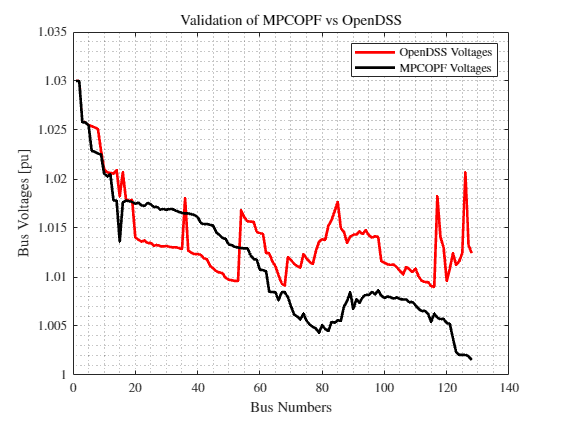

figure
% hold on;
linewidth = 2.0;
plot(V_opds, 'LineWidth', linewidth, 'Color', 'r');
hold on;
plot(V_copf, 'LineWidth', linewidth, 'Color', 'k')
legend({"OpenDSS Voltages", strcat(simName, " Voltages")});
title(strcat("Validation of ", simName, " vs OpenDSS"));
ylabel("Bus Voltages [pu]")
xlabel("Bus Numbers");
grid minor;
hold off;